## Main file 

Load data to fit

2/22/2023 Nanta

## Load data


clear variables

DTGdata_all = load('DTGdata_biomass.mat');

## Fit with 3 curves 

% Data and name
Data = ["PineExtFree_20Kpm_R1"];

Name = ["Pine Ext-free"];

% Other data
%{
Data = ["Pine20Kpm_R1","Pine20Kpm_R2","PineExtFree_20Kpm_R1","PineExtFree_20Kpm_R2",...
        "PP20Kpm_R4","PP20Kpm_R5","PPExtFree_20Kpm_R1","PPExtFree_20Kpm_R2","PPExtFree_20Kpm_R3",...
        "Birch_20Kpm_R1","Birch_20Kpm_R2", "BirchExtFree_20Kpm_R1","BirchExtFree_20Kpm_R2",...
        "Oak_20Kpm_R1","Oak_20Kpm_R2","OakExtFree_20Kpm_R1","OakExtFree_20Kpm_R2"];

samplename = ["Pine","Pine","Pine Ext-free","Pine Ext-free",...
              "Potato peel","Potato peel","Potato peel Ext-free","Potato peel Ext-free","Potato peel Ext-free",...
              "Birch","Birch","Birch Ext-free","Birch Ext-free",...
              "Oak","Oak","Oak Ext-free","Oak Ext-free"];

DataSW = ["BarkPine_20Kpm_R1","BarkPine_20Kpm_R2","BarkPineExtFree_20Kpm_R1","BarkPineExtFree_20Kpm_R2",...
          "Switchgrass_20Kpm_R1","Switchgrass_20Kpm_R2","SwitchgrassExtFree_20Kpm_R1","SwitchgrassExtFree_20Kpm_R2"]

NameSW = ["Bark","Bark","Bark Ext-free","Bark Ext-free","Swtichgrass","Swtichgrass","Swtichgrass Ext-free","Swtichgrass Ext-free"]
%}

beta = 20

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         2      0.02523        81       834     1.782e-06

MultiStart completed the runs from all start points.

The local solver ran once and converged with a positive local solver exit flag.


bb_fm =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063


fval_msfm = 0.0252

exitflag = 1

outputMS = struct with fields:
                funcCount: 844
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.4266 246.0759 0.5366 11.6999 145.0650 0.2331 18.2503 31.5419 0.2063]
        Fval: 0.0252
    Exitflag: 2
      Output: [1×1 struct]
          X0: {[11.9000 218 0.5000 11.1000 105.2000 0.3000 17.8000 53.5000 0.2000]}


fval_msfm = 0.0252

Rsq_msfm = 0.9986

T_peakC1 = 380.5602

T_peakC2 = 336.5946

T_peakC3 = 388.5516

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.fig"

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.png"

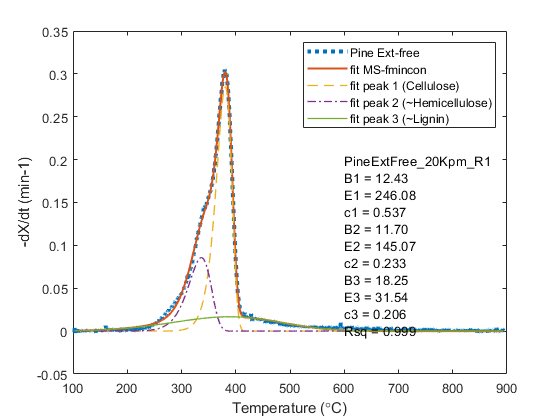

output =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063    0.9986  380.5602  336.5946  388.5516    0.9800


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


% fit with 3 curves
for i=1:length(Data)
    [FitResults3curves.(Data(i)).output, FitResults3curves.(Data(i)).outputMS, FitResults3curves.(Data(i)).solutions] = DTG_fit_3curves_biomass_fnc(DTGdata_all.(Data(i)),Name(i),Data(i))    
end


%save('FitResults3curves.mat','FitResults3curves');

% Extracting results
for i=1:length(Data)
    % output columns are
    % B1 E1 c1 B2 E2 c2 B3 E3 c3 Rsq_msfm T_peakC1 T_peakC2 T_peakC3 AreaFit/AreaExp   
    output3curves(i,:) = FitResults3curves.(Data(i)).output;

end

## Fit with 5 curves 

beta = 20

DTG = function_handle with value:
    @(x,xdata)x(3).*10^(x(2)/x(1)).*exp(-x(2)./xdata/R).*funExp(x(1),x(2),xdata)+x(6).*10^(x(5)/x(4)).*exp(-x(5)./xdata/R).*funExp(x(4),x(5),xdata)+x(9).*10^(x(8)/x(7)).*exp(-x(8)./xdata/R).*funExp(x(7),x(8),xdata)+x(12).*10^(x(11)/x(10)).*exp(-x(11)./xdata/R).*funExp(x(10),x(11),xdata)+x(15).*10^(x(14)/x(13)).*exp(-x(14)./xdata/R).*funExp(x(13),x(14),xdata)


    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         2       0.1166        52       855       0.03994

MultiStart completed the runs from all start points.

The local solver ran once and converged with a positive local solver exit flag.


bb_fm =    12.4252  217.8234    0.6040   11.6420  105.0460    0.1393   11.6056  105.6041    0.0963   17.5867   53.2948    0.0737   19.1969   30.9164    0.0946


fval_msfm = 0.1166

exitflag = 1

outputMS = struct with fields:
                funcCount: 871
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.4252 217.8234 0.6040 11.6420 105.0460 0.1393 11.6056 105.6041 0.0963 17.5867 53.2948 0.0737 19.1969 30.9164 0.0946]
        Fval: 0.1166
    Exitflag: 2
      Output: [1×1 struct]
          X0: {[11.9000 218 0.4000 10.8000 105 0.2000 11.1000 105.2000 0.2000 17.8000 53.5000 0.2000 19.6000 30 0.1000]}


fval_msfm = 0.1166

Rsq_msfm = 0.9934

T_peakC1 = 379.2413

T_peakC2 = 323.4858

T_peakC3 = 324.9817

T_peakC4 = 483.2650

T_peakC5 = 400.7704

figN = "./PineExtFree_20Kpm_R1_5curves_NormalBound_23728.fig"

figN = "./PineExtFree_20Kpm_R1_5curves_NormalBound_23728.png"

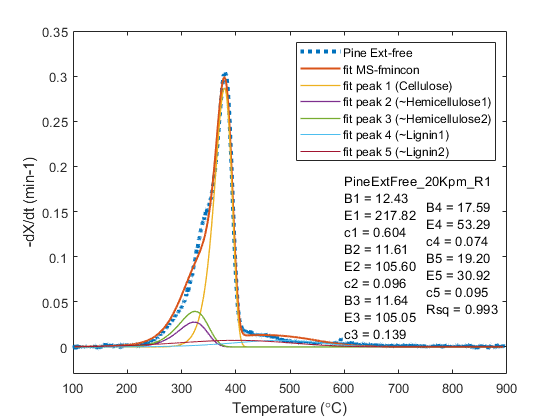

output =    12.4252  217.8234    0.6040   11.6056  105.6041    0.0963   11.6420  105.0460    0.1393   17.5867   53.2948    0.0737   19.1969   30.9164    0.0946    0.9934  379.2413  323.4858  324.9817  483.2650  400.7704    1.0120


FitResults5curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults5curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults5curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


% fit with 5 curves
for i=1:length(Data)
    [FitResults5curves.(Data(i)).output, FitResults5curves.(Data(i)).outputMS, FitResults5curves.(Data(i)).solutions] = DTG_fit_5curves_biomass_fnc(DTGdata_all.(Data(i)),Name(i),Data(i)) 
end

% Extracting results
for i=1:length(Data)
    % output columns are
    % B1 E1 c1 B2 E2 c2 B3 E3 c3 B4 E4 c4 B5 E5 c5 Rsq_msfm T_peakC1 T_peakC2 T_peakC3 T_peakC4 T_peakC5 AreaFit/AreaExp
    output5curves(i,:) = FitResults5curves.(Data(i)).output;

end